# Обучение нейросети PeaksNet

Загрузка данных для обучения:

load Train_Data.mat;
load Train_Value.mat;

Загрузка данных для валидации/тестирования:

load Test_Data.mat;
load Test_Value.mat;

Формирование архитектуры нейросети:

layers = ...
    [sequenceInputLayer(1,"Name","sequence")
    lstmLayer(100,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(6,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Задание параметров обучения:

options = trainingOptions('adam', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',30, ...
    'ValidationData',{Test_Data,Test_Value}, ...
    'InitialLearnRate',0.001, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress');

Непосредственно процесс обучения нейросети:

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:01 |       10.00% |       17.67% |       1.8406 |       1.8000 |          0.0010 |


|       1 |          50 |       00:00:12 |       26.67% |       33.00% |       1.6296 |       1.5539 |          0.0010 |


|       1 |         100 |       00:00:23 |       46.67% |       33.00% |       1.5339 |       1.5190 |          0.0010 |


|       2 |         150 |       00:00:42 |       36.67% |       36.67% |       1.7132 |       1.4374 |          0.0010 |


|       2 |         200 |       00:00:58 |       30.00% |       28.67% |       1.6311 |       1.6740 |          0.0010 |


|       3 |         250 |       00:01:10 |       40.00% |       36.67% |       1.5119 |       1.4086 |          0.0010 |


|       3 |         300 |       00:01:24 |       30.00% |       37.33% |       1.5180 |       1.3601 |          0.0010 |


|       4 |         350 |       00:01:38 |       50.00% |       36.33% |       1.3801 |       1.4333 |          0.0010 |


|       4 |         400 |       00:01:50 |       36.67% |       56.00% |       1.2698 |       1.0865 |          0.0010 |


|       5 |         450 |       00:02:02 |       70.00% |       60.67% |       1.0224 |       1.0434 |          0.0010 |


|       5 |         500 |       00:02:13 |       73.33% |       63.67% |       0.7729 |       0.8649 |          0.0010 |


|       6 |         550 |       00:02:25 |       66.67% |       66.00% |       0.6678 |       0.7919 |          0.0010 |


|       6 |         600 |       00:02:42 |       80.00% |       64.00% |       0.7489 |       0.9874 |          0.0010 |


|       7 |         650 |       00:02:54 |       56.67% |       73.33% |       0.9069 |       0.7181 |          0.0010 |


|       7 |         700 |       00:03:06 |       83.33% |       77.00% |       0.6883 |       0.6506 |          0.0010 |


|       8 |         750 |       00:03:18 |       63.33% |       72.33% |       0.6258 |       0.5660 |          0.0010 |


|       8 |         800 |       00:03:30 |       83.33% |       84.00% |       0.4551 |       0.4327 |          0.0010 |


|       9 |         850 |       00:03:43 |       83.33% |       86.33% |       0.3017 |       0.3838 |          0.0010 |


|       9 |         900 |       00:04:01 |       86.67% |       84.00% |       0.3746 |       0.4473 |          0.0010 |


|      10 |         950 |       00:04:14 |       96.67% |       92.00% |       0.2318 |       0.2724 |          0.0010 |


|      10 |        1000 |       00:04:27 |       93.33% |       93.00% |       0.2003 |       0.2203 |          0.0010 |


|      11 |        1050 |       00:04:42 |       90.00% |       90.33% |       0.3049 |       0.2332 |          0.0010 |


|      11 |        1100 |       00:04:56 |       93.33% |       92.33% |       0.2912 |       0.2205 |          0.0010 |


|      12 |        1150 |       00:05:07 |       96.67% |       95.33% |       0.1669 |       0.1724 |          0.0010 |


|      12 |        1200 |       00:05:20 |       93.33% |       85.67% |       0.2126 |       0.3452 |          0.0010 |


|      13 |        1250 |       00:05:32 |       93.33% |       96.33% |       0.2635 |       0.1742 |          0.0010 |


|      13 |        1300 |       00:05:51 |       93.33% |       97.00% |       0.1871 |       0.1441 |          0.0010 |


|      14 |        1350 |       00:06:04 |       93.33% |       95.67% |       0.2790 |       0.1462 |          0.0010 |


|      14 |        1400 |       00:06:24 |      100.00% |       97.67% |       0.0842 |       0.1042 |          0.0010 |


|      15 |        1450 |       00:06:35 |       93.33% |       87.33% |       0.1083 |       0.3399 |          0.0010 |


|      15 |        1500 |       00:06:47 |      100.00% |       97.67% |       0.1320 |       0.1101 |          0.0010 |


|      16 |        1550 |       00:06:59 |      100.00% |       89.00% |       0.0537 |       0.3036 |          0.0010 |


|      16 |        1600 |       00:07:10 |       96.67% |       94.33% |       0.1476 |       0.1953 |          0.0010 |


|      17 |        1650 |       00:07:21 |      100.00% |       97.00% |       0.0723 |       0.1184 |          0.0010 |


|      17 |        1700 |       00:07:33 |       90.00% |       96.00% |       0.2698 |       0.1219 |          0.0010 |


|      18 |        1750 |       00:07:48 |      100.00% |       97.67% |       0.0646 |       0.0981 |          0.0010 |


|      18 |        1800 |       00:08:01 |       96.67% |       98.33% |       0.1373 |       0.0888 |          0.0010 |


|      19 |        1850 |       00:08:13 |       96.67% |       96.67% |       0.1866 |       0.1492 |          0.0010 |


|      19 |        1900 |       00:08:24 |      100.00% |       98.33% |       0.0324 |       0.0896 |          0.0010 |


|      20 |        1950 |       00:08:35 |       66.67% |       83.33% |       0.8587 |       0.3992 |          0.0010 |


|      20 |        2000 |       00:08:47 |      100.00% |       97.33% |       0.0870 |       0.1325 |          0.0010 |


|      21 |        2050 |       00:09:06 |       96.67% |       98.33% |       0.2088 |       0.1076 |          0.0010 |


|      21 |        2100 |       00:09:19 |      100.00% |       97.67% |       0.0428 |       0.0941 |          0.0010 |


|      22 |        2150 |       00:09:30 |       96.67% |       98.67% |       0.1479 |       0.0872 |          0.0010 |


|      22 |        2200 |       00:09:43 |      100.00% |       98.33% |       0.0451 |       0.0827 |          0.0010 |


|      23 |        2250 |       00:10:01 |       96.67% |       98.67% |       0.1278 |       0.0788 |          0.0010 |


|      23 |        2300 |       00:10:13 |      100.00% |       98.67% |       0.0223 |       0.0828 |          0.0010 |


|      24 |        2350 |       00:10:28 |       93.33% |       98.00% |       0.1891 |       0.0920 |          0.0010 |


|      24 |        2400 |       00:10:44 |      100.00% |       98.67% |       0.0319 |       0.0771 |          0.0010 |


|      25 |        2450 |       00:10:56 |       93.33% |       98.67% |       0.2758 |       0.0692 |          0.0010 |


|      25 |        2500 |       00:11:07 |       93.33% |       98.67% |       0.2740 |       0.0725 |          0.0010 |


|      26 |        2550 |       00:11:29 |      100.00% |       98.67% |       0.0254 |       0.0747 |          0.0010 |


|      26 |        2600 |       00:11:43 |      100.00% |       99.00% |       0.0214 |       0.0690 |          0.0010 |


|      27 |        2650 |       00:11:54 |      100.00% |       97.00% |       0.0590 |       0.1101 |          0.0010 |


|      27 |        2700 |       00:12:07 |       96.67% |       98.33% |       0.1850 |       0.0761 |          0.0010 |


|      28 |        2750 |       00:12:24 |       96.67% |       98.67% |       0.1306 |       0.0712 |          0.0010 |


|      28 |        2800 |       00:12:36 |       96.67% |       97.67% |       0.1238 |       0.0942 |          0.0010 |


|      29 |        2850 |       00:12:49 |       96.67% |       98.67% |       0.1636 |       0.0711 |          0.0010 |


|      29 |        2900 |       00:13:07 |      100.00% |       99.00% |       0.0205 |       0.0806 |          0.0010 |


|      30 |        2950 |       00:13:21 |      100.00% |       99.00% |       0.0652 |       0.0701 |          0.0010 |


|      30 |        3000 |       00:13:33 |      100.00% |       99.00% |       0.0426 |       0.0680 |          0.0010 |


|      31 |        3050 |       00:13:50 |      100.00% |       99.00% |       0.0261 |       0.0626 |          0.0010 |


|      31 |        3100 |       00:14:01 |      100.00% |       99.00% |       0.0266 |       0.0650 |          0.0010 |


|      32 |        3150 |       00:14:12 |      100.00% |       99.00% |       0.0229 |       0.0658 |          0.0010 |


|      32 |        3200 |       00:14:30 |      100.00% |       93.00% |       0.0290 |       0.1753 |          0.0010 |


|      33 |        3250 |       00:14:42 |      100.00% |       98.67% |       0.0287 |       0.0837 |          0.0010 |


|      33 |        3300 |       00:14:53 |      100.00% |       99.00% |       0.0157 |       0.0634 |          0.0010 |


|      34 |        3350 |       00:15:12 |       96.67% |       99.00% |       0.1257 |       0.0643 |          0.0010 |


|      34 |        3400 |       00:15:24 |      100.00% |       99.00% |       0.0188 |       0.0641 |          0.0010 |


|      35 |        3450 |       00:15:35 |       96.67% |       98.67% |       0.0657 |       0.0699 |          0.0010 |


|      35 |        3500 |       00:15:51 |       96.67% |       92.00% |       0.1040 |       0.1673 |          0.0010 |


|      36 |        3550 |       00:16:04 |       96.67% |       99.00% |       0.1140 |       0.0699 |          0.0010 |


|      36 |        3600 |       00:16:15 |      100.00% |       98.00% |       0.0162 |       0.0931 |          0.0010 |


|      37 |        3650 |       00:16:27 |      100.00% |       98.33% |       0.0305 |       0.0740 |          0.0010 |


|      37 |        3700 |       00:16:50 |      100.00% |       99.00% |       0.0347 |       0.0718 |          0.0010 |


|      38 |        3750 |       00:17:05 |      100.00% |       99.00% |       0.0198 |       0.0674 |          0.0010 |


|      38 |        3800 |       00:17:16 |       93.33% |       99.00% |       0.3129 |       0.0665 |          0.0010 |


|      39 |        3850 |       00:17:32 |      100.00% |       99.00% |       0.0102 |       0.0630 |          0.0010 |


|      39 |        3900 |       00:17:46 |      100.00% |       99.00% |       0.0189 |       0.0630 |          0.0010 |


|      40 |        3950 |       00:17:58 |       96.67% |       98.00% |       0.0751 |       0.0766 |          0.0010 |


|      40 |        4000 |       00:18:09 |       93.33% |       98.67% |       0.2544 |       0.0722 |          0.0010 |


|      41 |        4050 |       00:18:27 |       83.33% |       82.33% |       0.7642 |       0.8376 |          0.0010 |


|      41 |        4100 |       00:18:39 |       96.67% |       98.67% |       0.2252 |       0.1637 |          0.0010 |


|      42 |        4150 |       00:18:50 |       96.67% |       99.00% |       0.1529 |       0.1304 |          0.0010 |


|      42 |        4200 |       00:19:04 |      100.00% |       99.00% |       0.0597 |       0.0931 |          0.0010 |


|      43 |        4250 |       00:19:22 |       96.67% |       99.00% |       0.0610 |       0.0835 |          0.0010 |


|      43 |        4300 |       00:19:34 |       93.33% |       93.67% |       0.1903 |       0.1561 |          0.0010 |


|      44 |        4350 |       00:19:46 |       96.67% |       99.00% |       0.1625 |       0.0811 |          0.0010 |


|      44 |        4400 |       00:20:07 |      100.00% |       99.00% |       0.0386 |       0.0866 |          0.0010 |


|      45 |        4450 |       00:20:18 |       90.00% |       99.00% |       0.4313 |       0.0808 |          0.0010 |


|      45 |        4500 |       00:20:30 |       93.33% |       99.00% |       0.2700 |       0.0770 |          0.0010 |


|      46 |        4550 |       00:20:42 |      100.00% |       99.00% |       0.0299 |       0.0735 |          0.0010 |


|      46 |        4600 |       00:20:53 |      100.00% |       99.00% |       0.0384 |       0.0693 |          0.0010 |


|      47 |        4650 |       00:21:05 |       93.33% |       99.00% |       0.2322 |       0.0677 |          0.0010 |


|      47 |        4700 |       00:21:17 |       96.67% |       99.00% |       0.1168 |       0.0694 |          0.0010 |


|      48 |        4750 |       00:21:28 |       96.67% |       99.00% |       0.0778 |       0.0742 |          0.0010 |


|      48 |        4800 |       00:21:45 |      100.00% |       99.00% |       0.0238 |       0.0680 |          0.0010 |


|      49 |        4850 |       00:21:57 |      100.00% |       99.00% |       0.0214 |       0.0703 |          0.0010 |


|      49 |        4900 |       00:22:08 |       93.33% |       94.00% |       0.2293 |       0.2065 |          0.0010 |


|      50 |        4950 |       00:22:26 |      100.00% |       99.00% |       0.0315 |       0.0772 |          0.0010 |


|      50 |        5000 |       00:22:38 |      100.00% |       99.00% |       0.0299 |       0.0646 |          0.0010 |


|======================================================================================================================|


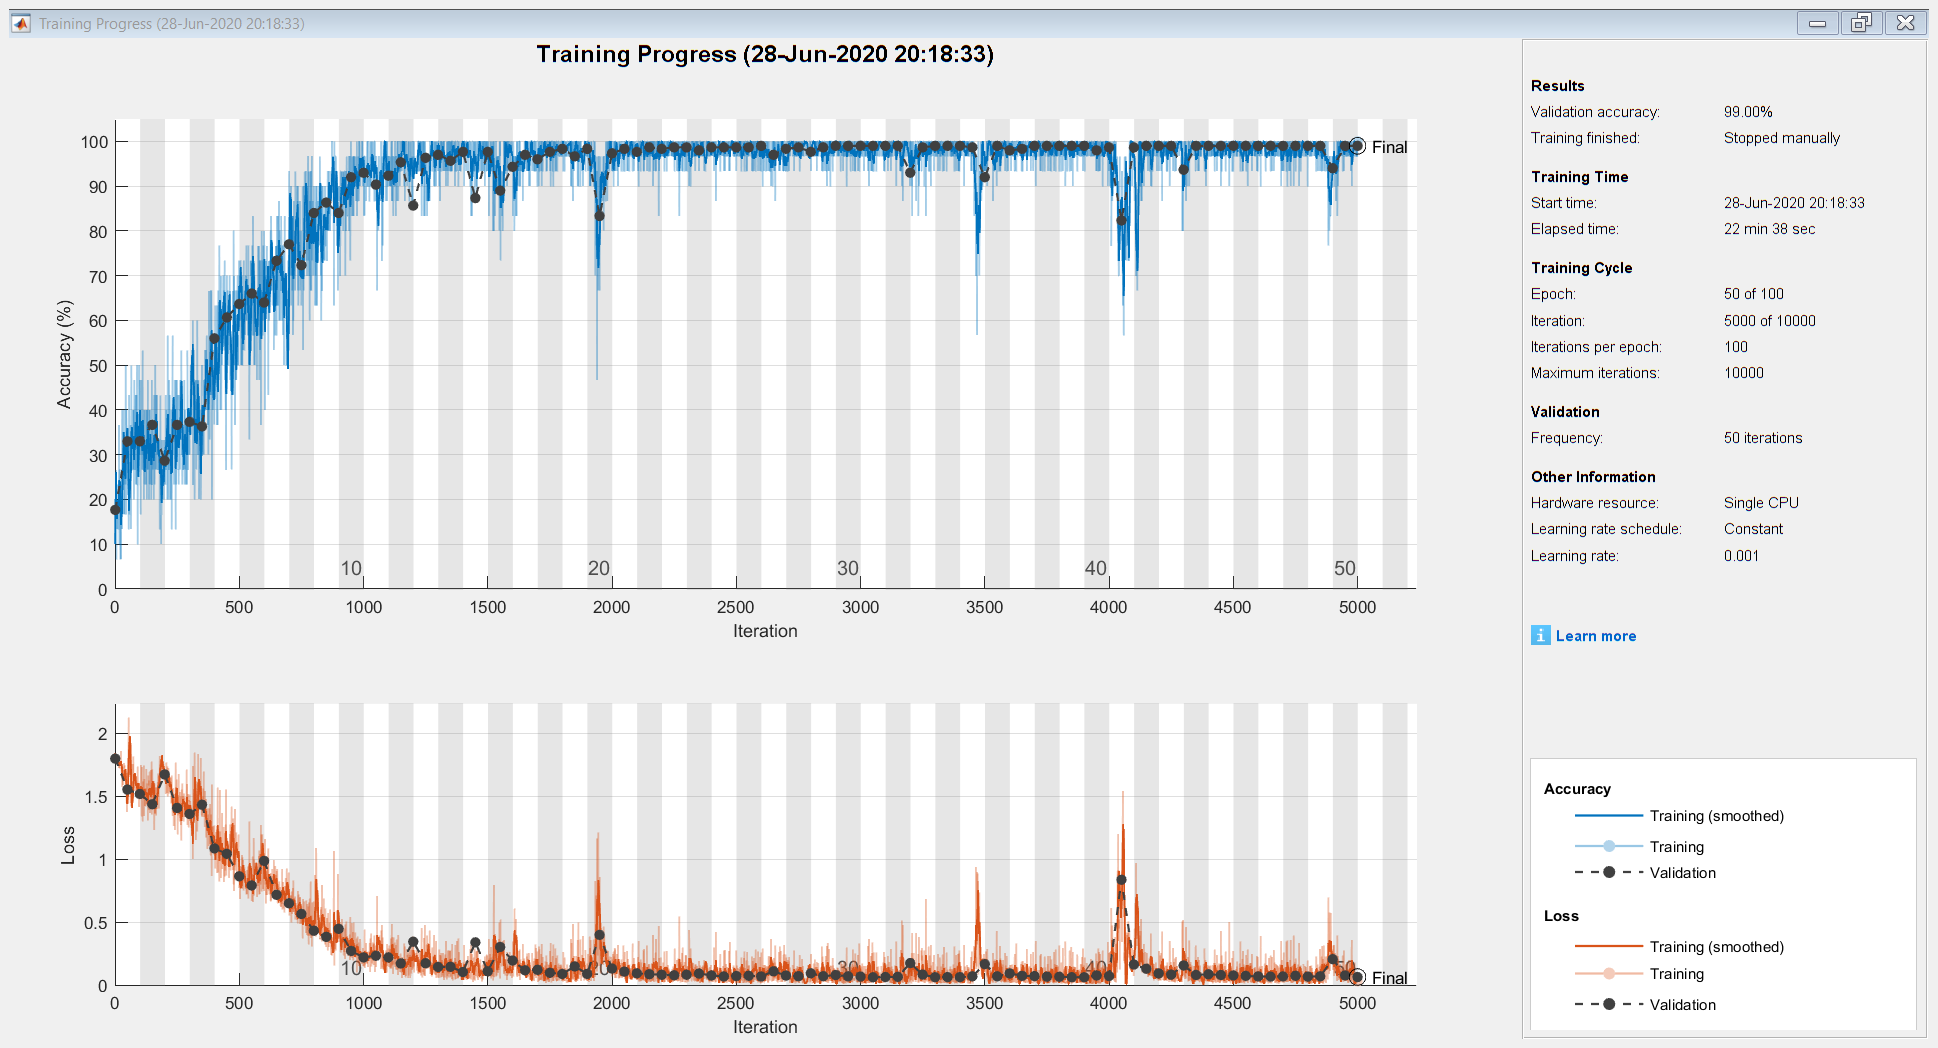

PeaksNet = trainNetwork(Train_Data,Train_Value,layers,options);

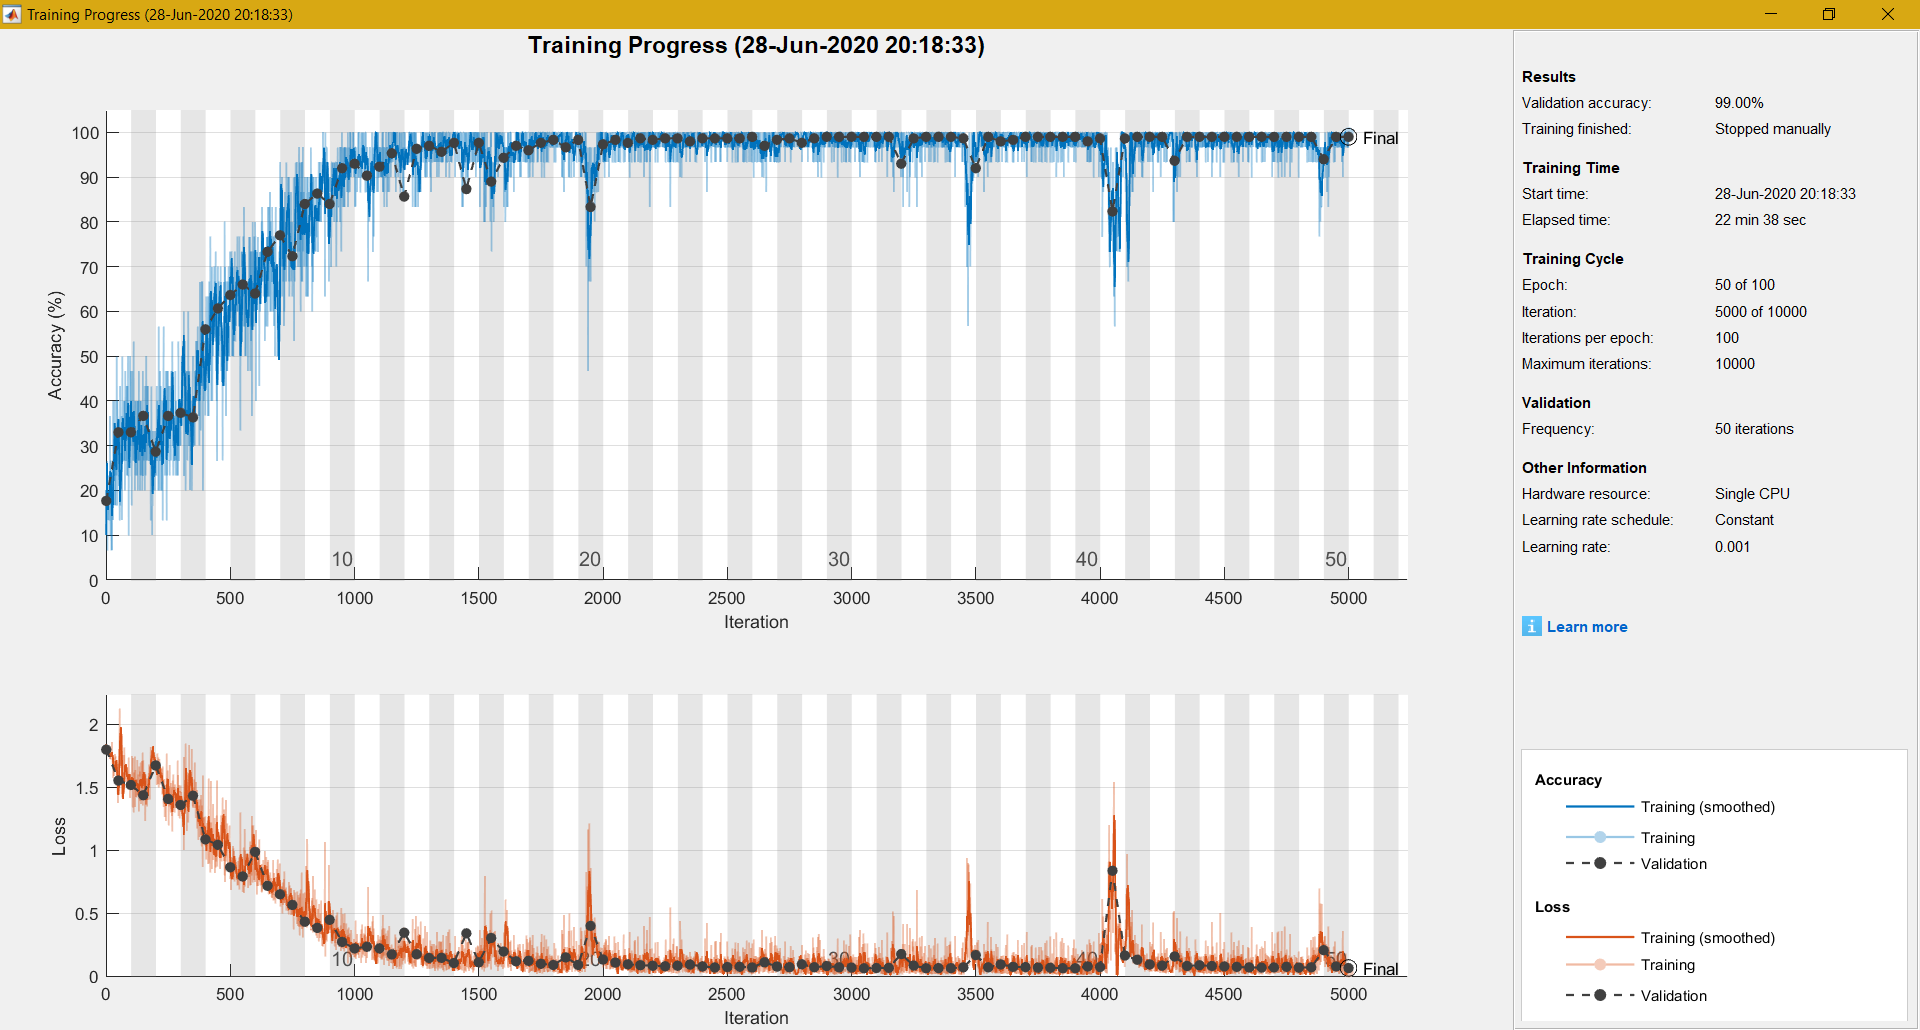

Вычисление точности работы нейросети на тестовых данных:

YPred = classify(PeaksNet,Test_Data);
acc = mean(YPred==Test_Value);
disp(acc);